## Generate train and test set

clear;

train_x = [-1.6:0.05:1.6];
train_y = 1.2 * sin(pi*train_x) - cos(2.4*pi*train_x);

test_x = [-1.6:0.01:1.6];
test_y = 1.2 * sin(pi*test_x) - cos(2.4*pi*test_x);

## a. Train with sequential mode

train_x_size = size(train_x);
train_num = train_x_size(2);

% for sequential mode
train_x_cell = num2cell(train_x);
train_y_cell = num2cell(train_y);

epochs = 200;

**When hidden_size n = [1, ..., 6]**

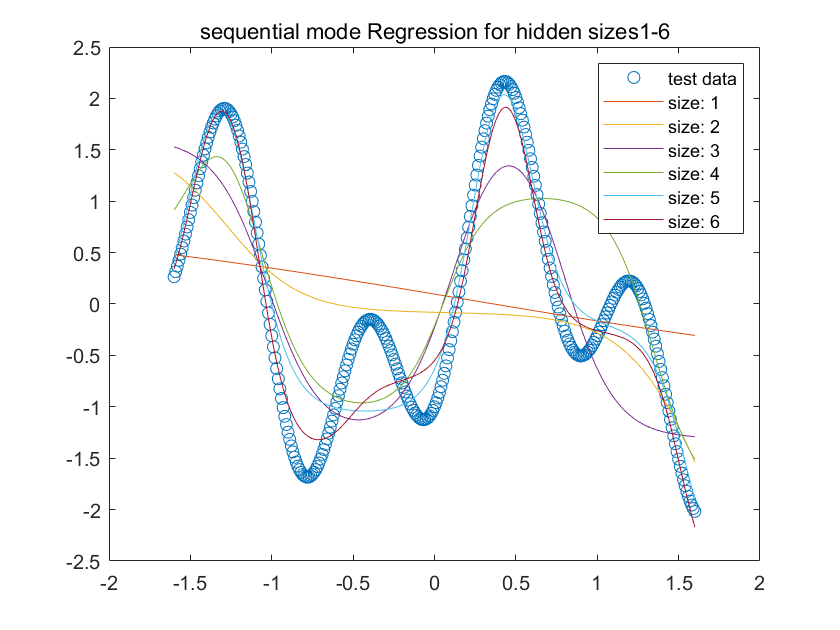

The average error in test set after100 epochs for each hidden size from1to6
   0.911044546056612   0.791579169702571   0.580400783197633   0.573969777296986   0.298667763801158   0.255215104199160
The average error in -3, 3 after100 epochs for each hidden size:
   0.737402721697615   2.700261134300090   1.460004871249016   1.520132378582982   2.496203950842778   2.354300786532550


sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [1:1:6], 100)

**When hidden_size = [7, 8,  9, 10]**

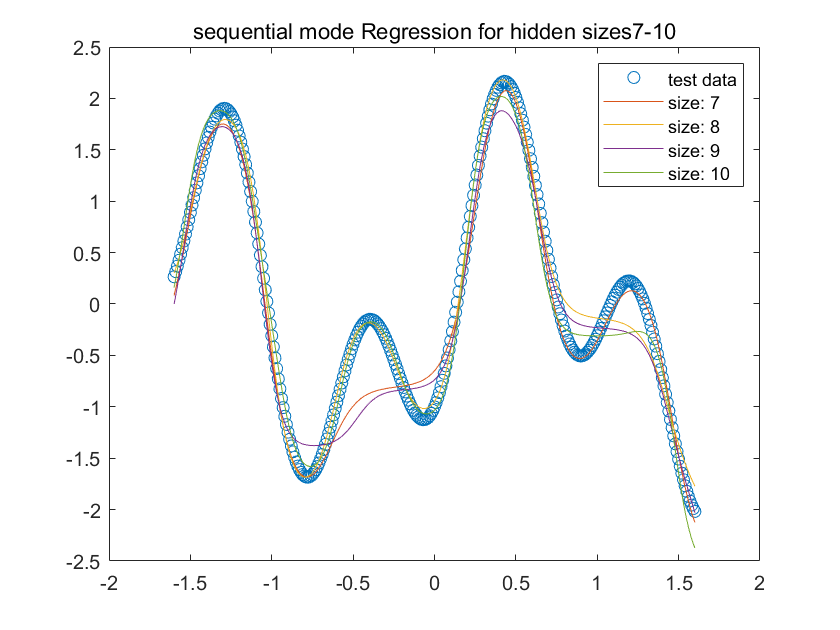

The average error in test set after100 epochs for each hidden size from7to10
   0.165886360383598   0.110865629165040   0.233370381386879   0.131591981041905
The average error in -3, 3 after100 epochs for each hidden size:
   2.370184155730812   1.993166859211010   2.525822307166524   2.327081637289558


sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [7:1:10], 100)

**When hidden_size = [20,  50, 100]**

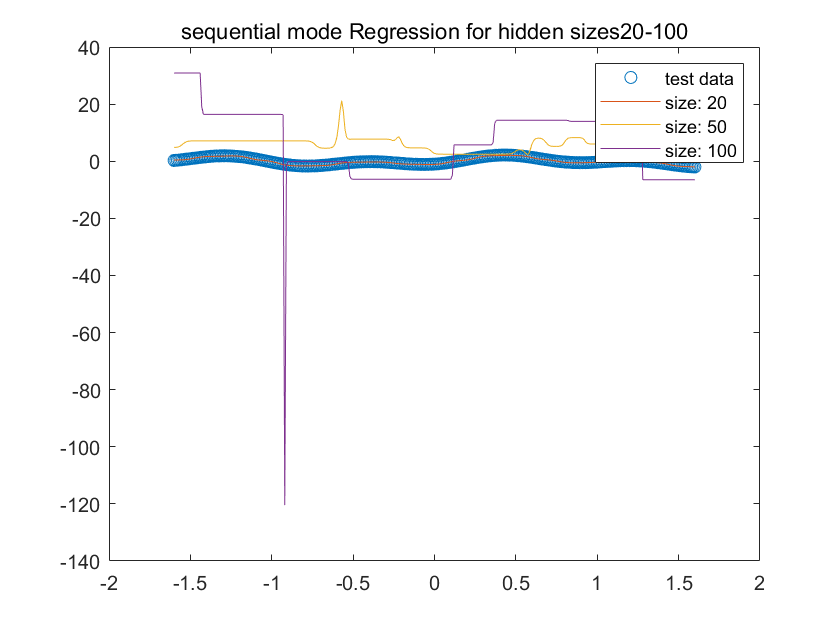

The average error in test set after100 epochs for each hidden size from20to100
   0.091071300854189   6.026655130201895  10.358303141695497
The average error in -3, 3 after100 epochs for each hidden size:
   1.0e+03 *
   0.001487359837198   0.044086432923329   1.958519192069844


sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [20, 50, 100], 100)

## b. Batch mode with trainlm

**When hidden_size n = [1, ..., 6]**

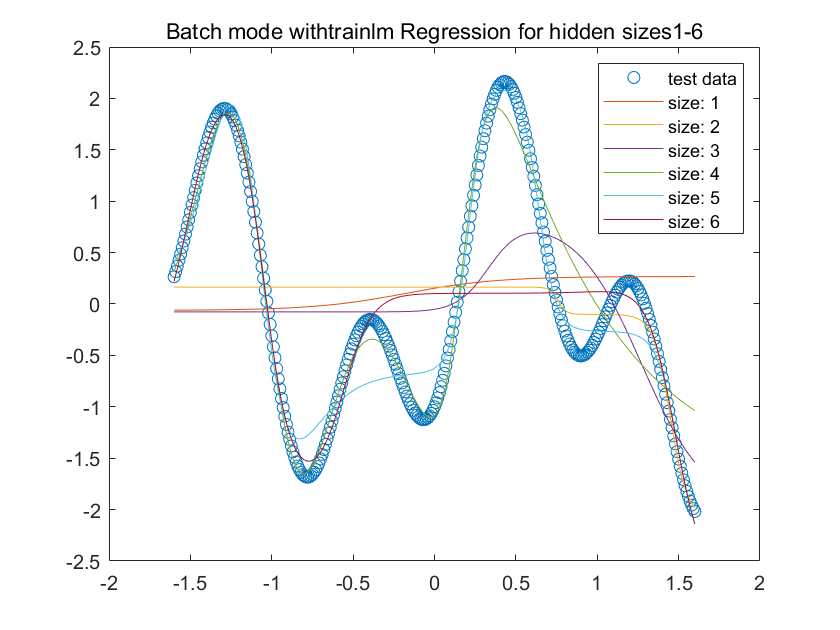

The average error in test set for each hidden size from1to6
   0.956686910629861   0.820416679518997   0.823526984307692   0.233292373094508   0.195831061230504   0.435338551269731
The average error in -3, 3 for each hidden size:
   0.706219056592401   1.767914546153452   1.846949613698605   1.866887187011764   2.120613906057712   2.489896312762530


    bt_train(train_x, train_y, test_x, test_y, [1:1:6], 'trainlm');

**When hidden_size = [7, 8,  9, 10]**

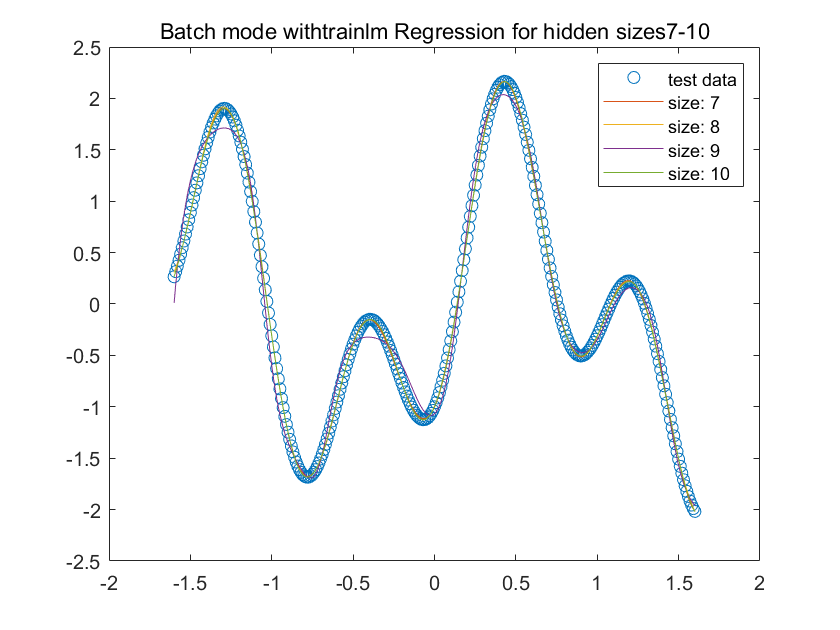

The average error in test set for each hidden size from7to10
   0.008839008412962   0.005137859043704   0.091013556007371   0.002099870322258
The average error in -3, 3 for each hidden size:
   3.361561723756132   2.026565947300732  10.806828886715639   2.081601592286401


bt_train(train_x, train_y, test_x, test_y, [7:1:10], 'trainlm');

**When hidden_size = [20,  50, 100]**

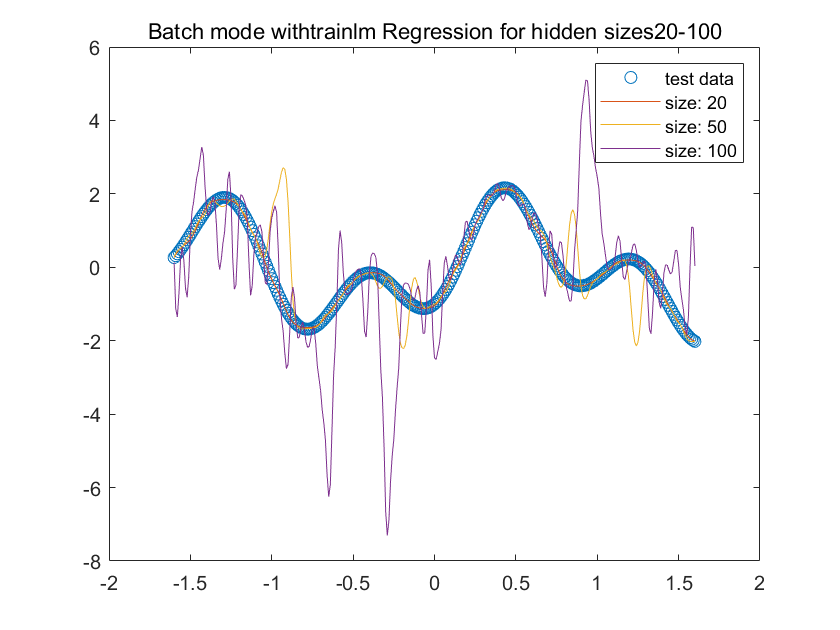

The average error in test set for each hidden size from20to100
   0.029446522334289   0.295412372840693   0.955213593835285
The average error in -3, 3 for each hidden size:
   2.291657814611649   1.974800433211565   1.749957071093439


bt_train(train_x, train_y, test_x, test_y, [20, 50, 100], 'trainlm');

## c. Batch mode with trainbr

**When hidden_size n = [1, ..., 6]**

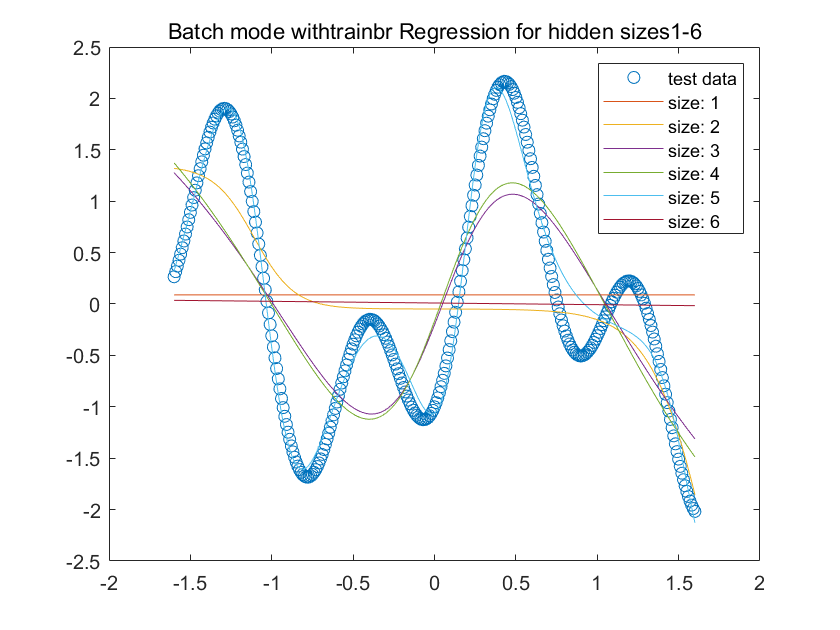

The average error in test set for each hidden size from1to6
   0.932959382507510   0.743508354263388   0.625803319589777   0.622339122076273   0.167860350913198   0.918470194018255
The average error in -3, 3 for each hidden size:
   0.720516111080088   3.351056109857002   2.736227108667817   2.851647570217623   3.048965137890502   0.799262927483982


bt_train(train_x, train_y, test_x, test_y, [1:1:6], 'trainbr');

**When hidden_size = [7, 8,  9, 10]**

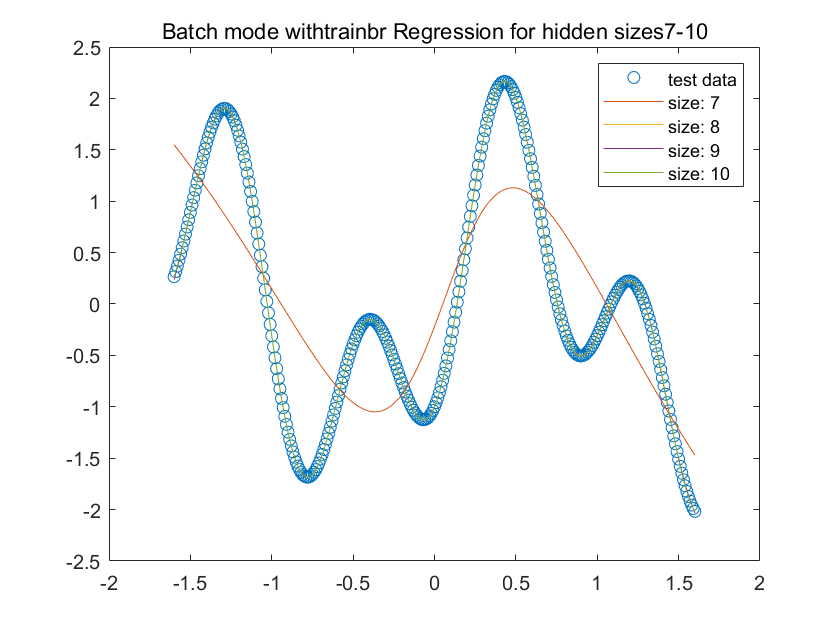

The average error in test set for each hidden size from7to10
   0.619440859124851   0.002587422843622   0.002200162206985   0.000709585508299
The average error in -3, 3 for each hidden size:
   3.560865418656703   1.573671531111160   2.397817441364176   1.380582685067534


bt_train(train_x, train_y, test_x, test_y, [7:1:10], 'trainbr');

**When hidden_size = [20,  50, 100]**

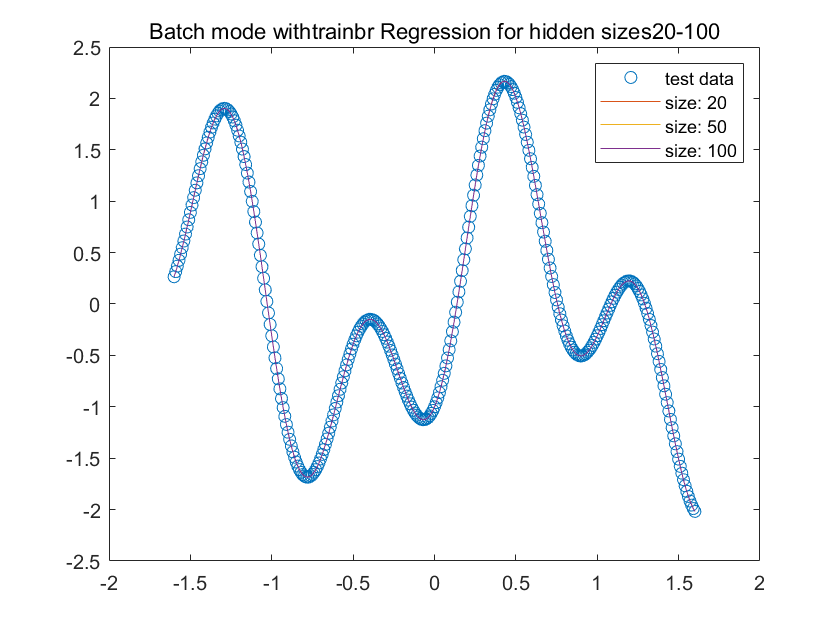

The average error in test set for each hidden size from20to100
   1.0e-03 *
   0.412414973019788   0.004464774193272   0.084255223355492
The average error in -3, 3 for each hidden size:
   1.973917117840295   0.787966700949913   1.671791133362295


bt_train(train_x, train_y, test_x, test_y, [20, 50, 100], 'trainbr');

function sq_train(x, y, test_x, test_y, train_num, hidden_sizes, epochs)
figure;
plot(test_x, test_y, 'o', 'DisplayName', 'test data');
hold on;

avg_err = zeros(size(hidden_sizes));
avg_err_o = zeros(size(hidden_sizes));

err_idx = 0;
for hidden_size = hidden_sizes
    err_idx = err_idx + 1;
    
    % one layer
    net = feedforwardnet(hidden_size);
    for epoch = 1:epochs
        idx = randperm(train_num); % shuffle the input
        net = adapt(net, x(:, idx), y(:, idx));
    end
    
    output = net(test_x);
    avg_err(err_idx) = mean(abs(output - test_y));
    
    % compute the values outside the x domain
    x_o = [-3, 3];
    y_o = 1.2 * sin(pi*x_o) - cos(2.4*pi*x_o);
    output_o = net(x_o);
    avg_err_o(err_idx) = mean(abs(output_o - y_o));
    
    plot(test_x, output, 'DisplayName', sprintf('size: %d', hidden_size));
    hold on;
end

title(strcat('sequential mode Regression for hidden sizes ', num2str(hidden_sizes(1)), '-', num2str(hidden_sizes(err_idx))));
legend;

disp(strcat('The average error in test set after ', num2str(epochs), ' epochs for each hidden size from ', num2str(hidden_sizes(1)), 'to', num2str(hidden_sizes(err_idx))));
disp(avg_err);

disp(strcat('The average error in -3, 3 after ', num2str(epochs), ' epochs for each hidden size:'));
disp(avg_err_o);

end

%% batch mode
function bt_train(x, y, test_x, test_y, hidden_sizes, trainFn)
figure;
plot(test_x, test_y, 'o', 'DisplayName', 'test data');
hold on;

avg_err = zeros(size(hidden_sizes));
avg_err_o = zeros(size(hidden_sizes));

err_idx = 0;
for hidden_size = hidden_sizes
    err_idx = err_idx + 1;
    
    net = feedforwardnet(hidden_size, trainFn);
    net.trainParam.epochs = 100;
    net = train(net, x, y);
    
    output = net(test_x);
    avg_err(err_idx) = mean(abs(output - test_y));
    
    % compute the values outside the x domain
    x_o = [-3, 3];
    y_o = 1.2 * sin(pi*x_o) - cos(2.4*pi*x_o);
    output_o = net(x_o);
    avg_err_o(err_idx) = mean(abs(output_o - y_o));
    
    plot(test_x, output, 'DisplayName', sprintf('size: %d', hidden_size));
    hold on;
end

title(strcat('Batch mode', ' with', trainFn, ' Regression for hidden sizes ', num2str(hidden_sizes(1)), '-', num2str(hidden_sizes(err_idx))));
legend;

disp(strcat('The average error in test set for each hidden size from ', num2str(hidden_sizes(1)), 'to', num2str(hidden_sizes(err_idx))));
disp(avg_err);

disp(strcat('The average error in -3, 3 for each hidden size:'));
disp(avg_err_o);

end